Initial Conditions - 

%critical point for oxygen
Tc=154.6; 
Pc=5.046e6; 
R=8.314;

%vanderwall's constants
A=(27*((R*Tc)^2))/(64*Pc);
B=(R*Tc)/(8*Pc);

%coefficients in constant pressure heat capacity
a = 28.167;
b = 0.630e-2;
c = -0.075e-5;

%reference state - 
H_ref = 0;
S_ref = 0;
T_ref = 298.15;
P_ref = 1e5;

axes for plotting 

T=[10 100 200 300 400 500 600]+273.15;
P=logspace(0,2,300)*1e5;
enth = zeros(1, size(P, 2));
ent = zeros(1, size(P, 2));
nt = size(T, 2);
np = size(P, 2);

enthalpy plot (KJ/mol Vs Bar)-

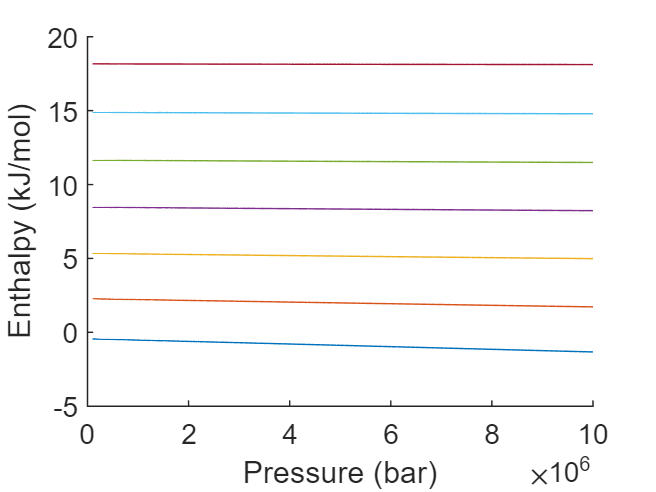

hold on;
for t = 1:nt
    for p = 1:np
        enth(1, p) = 0.001*enthalpy(T(1, t), P(1, p), [T_ref, P_ref, H_ref], [A B], [a b c], R);
    end
    plot(P, enth);
end
xlabel("Pressure (bar)");
ylabel("Enthalpy (kJ/mol)");
hold off

entropy plot (J/K Vs Bar)- 

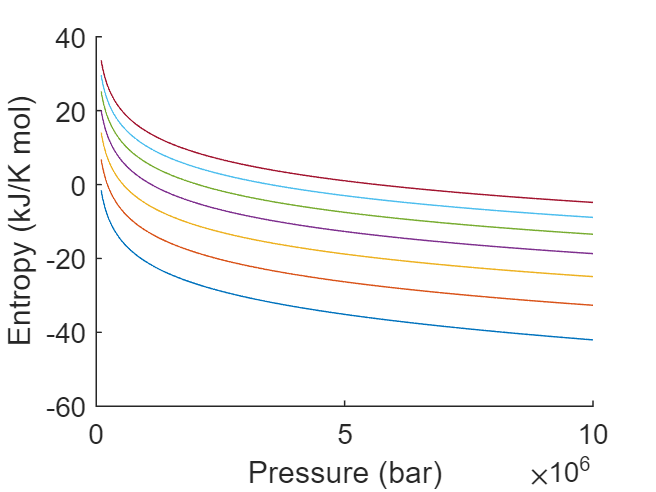

figure;
hold on
for t = 1:nt
    for p = 1:np
        ent(1, p) = entropy(T(1, t), P(1, p), [T_ref, P_ref, S_ref], [A B], [a b c], R);
    end
    plot(P, ent);
end
xlabel("Pressure (bar)");
ylabel("Entropy (kJ/K mol)");